clear;
load C01_dataE2.mat;
groupTest=[3,9,15];
groupTrain=[1:2,4:8,10:14,16:18];
for i=1:size(groupTrain,2)
    XTrain{i,1}=inputs{groupTrain(i)};
    YTrain{i,1}=outputs{groupTrain(i)};
end

numResponses = 1;
numFeatures = 31;
numHiddenUnits = 200;
H0 = zeros(numHiddenUnits,1);
C0 = zeros(numHiddenUnits,1);
mu = mean([XTrain{:}],2);
sig = std([XTrain{:}],0,2);
%测试输出
for i=1:size(groupTest,2)
    XTest{i,1}=inputs{groupTest(i)};
    YTest{i,1}=outputs{groupTest(i)};
end
for i = 1:numel(XTest)
    XTest{i} = (XTest{i} - mu) ./ sig;
end
in=XTest{1,1};
out=zeros(1,100);

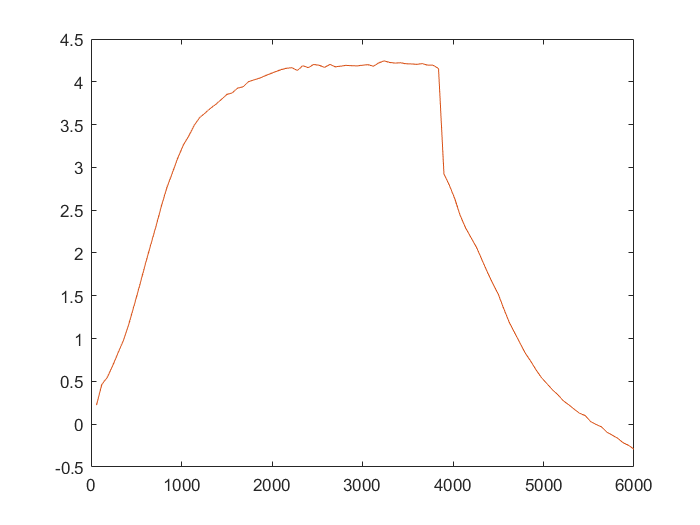

YTest_Pred = predict(net,XTest{1},'MiniBatchSize',1);
tNet=net;
for i=1:100
    [tNet,out(i)] = predictAndUpdateState(tNet,in(:,i));
end
t=60:60:6000;
figure

plot(t,YTest_Pred,'--')
hold on;
plot(t,out)